## **2. Signals**

A signal is a function representing a physical quantity or variable that contains information from a phenomenon, the signal can be one-dimensional as a sound wave, two-dimensional as an image, or a multidimensional singal.

## 2.1 Categorization

#### 2.1.1 Continuous-Time signals

A signal is called continuous-time (analog) signal if the independent variable (time) is defined in a continuous interval, an is expressed by the function ***x(t) ***where ***t*** takes real values.

Note: Matlab is unable to work with continuous-time signals, however, it is possible to approximate to them using a discrete-time representation with a small time step.

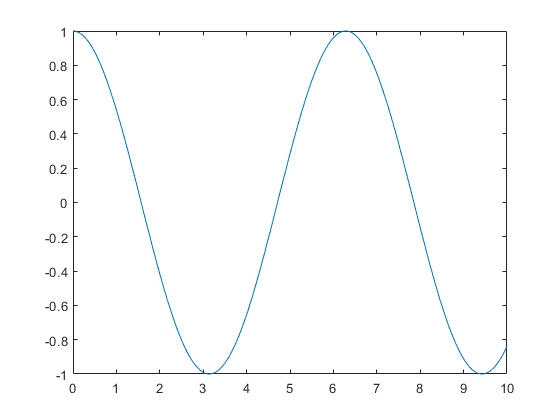

t = 0:0.01:10; % Time independent variables, time step = 0.01
y = cos(t); % Dependent varibale continuous in the interval
plot(t,y) % Function graph

#### 2.1.2 Discrete-Time Signals

It is often defined as a sequence of numbers defined in discrete times as is denoted by the function ***x[n]***, the independent variable is defined in a discrte interval, while the dependent variable is defined in a continuous set of values.

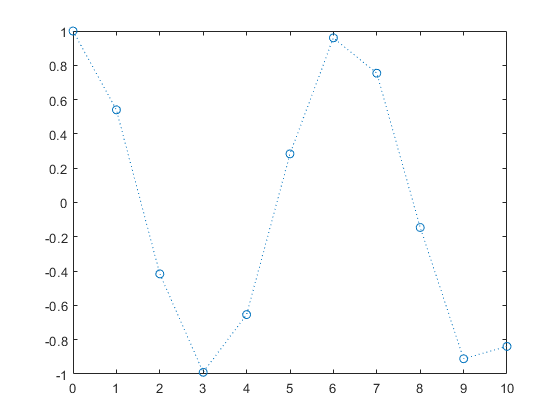

n = 0:10; % Discrete time with step 1
y = cos(n); % Dependent variable y[n], continuous set of values 
plot(n,y,':o')

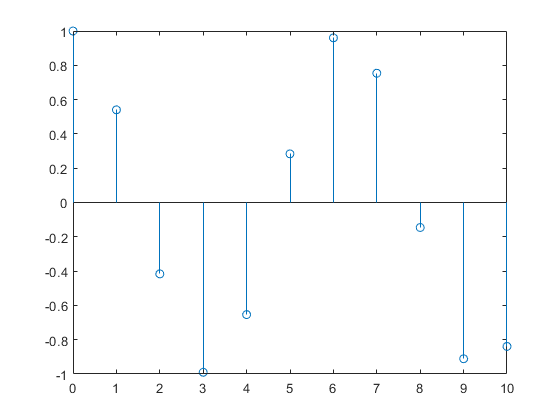

stem(n,y) % Plots a discrete time signal

Usually a discrete-time ***x[n]*** signal is obtained by sampling a continuous-time signal ***x(t)*** at a constant rate, for a sampling rate defined by ***Ts***, the discrte-time signal is defined as*** x[nTs].***

#### 2.1.3 Digital Signals

For the digital signals the dependent and the independent varibles takes values from a discrete set. The following signal was treatment to only use values,  y[n] = 1 or 0.

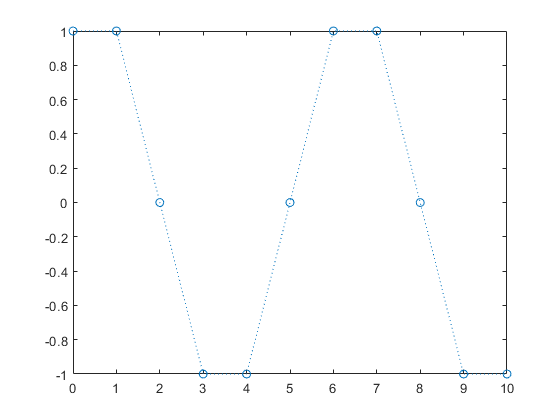

n = 0:10;
y = cos(n);
y = round(y);
plot(n,y,":o")

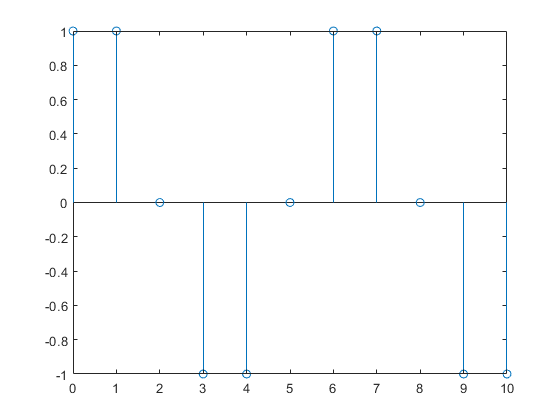

stem(n,y)

### 2.2 Basic Continuous-time signals

#### 2.2.1 Sinusoidal Signals

The basic definition from a sinusoidal signal is described below:

$x(t) = A \;cos(\Omega t+\theta)$;

***A: ***Is the  *A*mplitude;

$\Omega$: Is the angular frecuency in rad/s

$\theta:$ Is the Phase of the signal.

$T = \frac{2\pi}{\Omega} = \frac{1}{f}$ is the period of the signal and $f
$ is the frecuency.

Plot the signal $x(t) = 3cos(3\pi + \pi/3)$ in four periods.

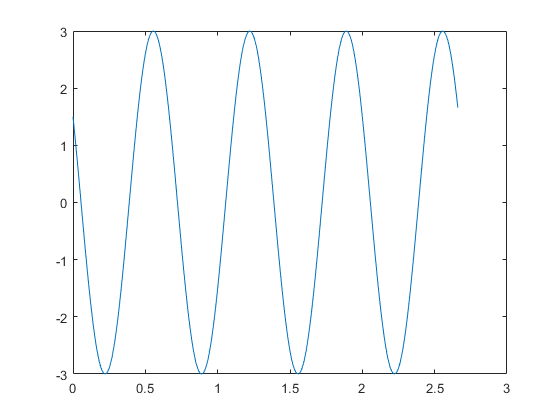

% Example

A = 3;
omega = 3*pi;
thita = pi/3;
T = 2*pi/omega;
t = 0:0.01:4*T;
x = A*cos(omega*t+thita);
plot(t,x)

It is called sinusioidal signal because and not cosinusoidal because a sinusoidal signal is a cosine singal with a different phase, as you can see below:

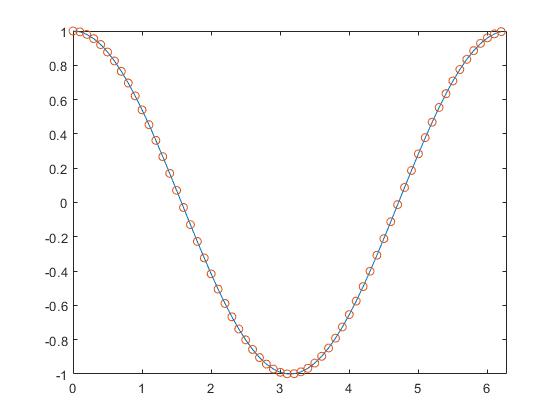

t=0:0.1:2*pi;
x1=cos(t);
x2=sin(t+pi/2);
plot(t,x1,t,x2,'o')
xlim([0 2*pi])